This is an interactive script thats lets you better visualize how frames look. I will build upon it over time as more people work on this lab/project. No point in making a live script that teaches people how to use the MATLAB DSP pipeline when the only person working with the MATLAB DSP pipeline is me.

close all; clear; clc

localDataPath = '/data/dataset-testing';        % Change this if your data is not in /data
captureName = 'test53.frames';

First we will process the frames to get the baseband signal and visualize it.

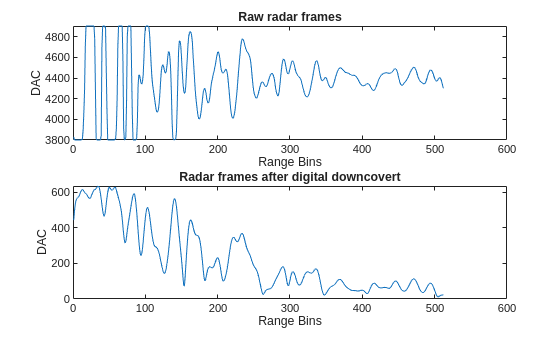

[frameTot, framesBB, frameRate] = ProcessFrames(localDataPath, captureName);
PlotFrames(frameTot, framesBB)

Now we can check if the tag(s) are visible, as needed. 

If it's a single tag, run the following:

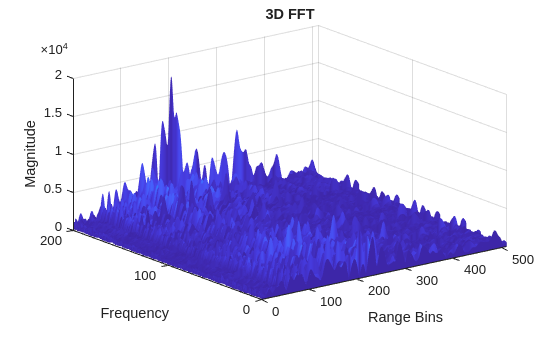

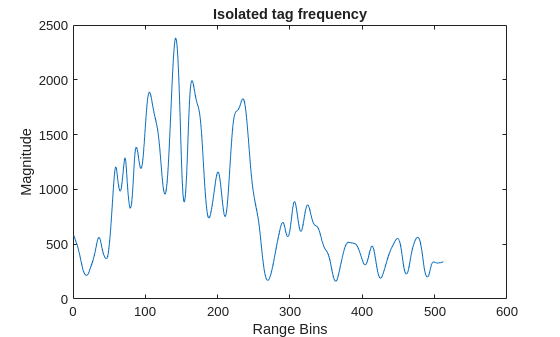

tagHz = 80;

[captureFT, tagFT] = ProcessFFT(framesBB, frameRate, tagHz);
PlotTag(captureFT, tagFT, frameRate)

If it's a dual tag, run the following:

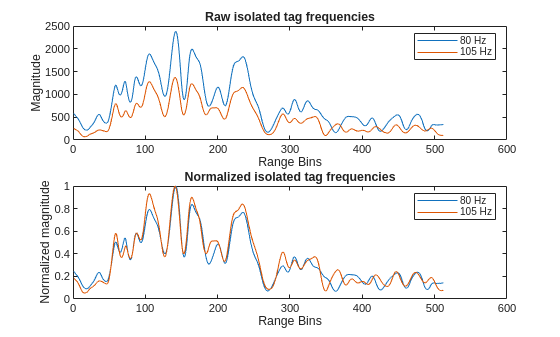

tag1Hz = 80;
tag2Hz = 105;


[captureFT, tag1FT] = ProcessFFT(framesBB, frameRate, tag1Hz);
[~, tag2FT] = ProcessFFT(framesBB, frameRate, tag2Hz);

tag1Name = strcat(num2str(tag1Hz), ' Hz');
tag2Name = strcat(num2str(tag2Hz), ' Hz');
PlotDualTag(captureFT, tag1FT, tag2FT, tag1Name, tag2Name, frameRate)